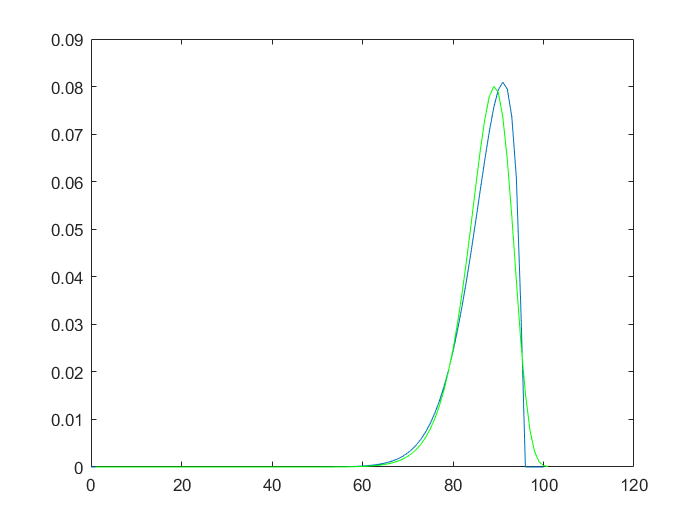

clear all;
close all;
clc;

load JND_first.mat;
load JND_second.mat;
load JND_third.mat;

% image 4 third JND
data_QF = JND_result_third(4, :);
data_distortion_level = 101 - data_QF;
% Plot pdf only based on DL
GEV_pd_DL = fitdist(data_distortion_level', 'GeneralizedExtremeValue');
pdf_DL = pdf(GEV_pd_DL, 0:100);
plot(0:100, pdf_DL);
hold on;
% Plot pdf based on P.T.R. of QF (reflect and shift).
pd_GEV_QF = fitdist(data_QF','GeneralizedExtremeValue');
pdf_GEV_QF = pdf(pd_GEV_QF,0:100);
pdf_GEV_QF_inverse = pdf_GEV_QF(end:-1:1);
plot(1:101,pdf_GEV_QF_inverse,'g');